% Datos proporcionados
litros_por_carga = 93; % litros de agua consumidos por carga
peso_carga = 10;          % peso de la carga en kg
cargas_por_semana = 7*7.14;  % número de cargas por semana
semanas_por_anio = 52;   % número de semanas en un año

% Calcular el total de agua consumida en 52 semanas
agua_consumida_total = litros_por_carga * cargas_por_semana * semanas_por_anio;

% Mostrar la cantidad total de agua consumida
fprintf('Cantidad total de agua consumida por la lavadora en 52 semanas: %.2f litros\n', ...
        agua_consumida_total);

Cantidad total de agua consumida por la lavadora en 52 semanas: 241703.28 litros



% Porcentajes de absorción de 25% a 50% en incrementos de 5%
porcentajes_absorcion = 0.25:0.05:0.50;

% Inicializar el vector para almacenar el agua tirada
agua_tirada_total_anual = zeros(size(porcentajes_absorcion));

% Calcular el agua tirada para cada porcentaje de absorción
for i = 1:length(porcentajes_absorcion)
    % Calcular el agua absorbida en litros
    agua_absorbida_por_carga = peso_carga * porcentajes_absorcion(i); % en litros
    % Calcular el agua que se tira por carga
    agua_tirada_por_carga = litros_por_carga - agua_absorbida_por_carga;
    % Asegurarse de que no se tenga un valor negativo
    agua_tirada_por_carga = max(agua_tirada_por_carga, 0); 
    % Calcular el agua tirada total en un año
    agua_tirada_total_anual(i) = agua_tirada_por_carga * cargas_por_semana * semanas_por_anio;
end

% Crear una tabla para mostrar los resultados
resultados = table(porcentajes_absorcion' * 100, agua_tirada_total_anual', ...
                   'VariableNames', {'Porcentaje_Absorcion', 'Agua_Tirada_Anual_Litros'});

% Agregar la cantidad total de agua consumida a la tabla
resultados.Total_Agua_Consumida_Litros = repmat(agua_consumida_total, height(resultados), 1);

% Mostrar la tabla
disp('Resultados:');

Resultados:


disp(resultados);

    Porcentaje_Absorcion    Agua_Tirada_Anual_Litros    Total_Agua_Consumida_Litros
    ____________________    ________________________    ___________________________

             25                    2.3521e+05                    2.417e+05         
             30                    2.3391e+05                    2.417e+05         
             35                    2.3261e+05                    2.417e+05         
             40                    2.3131e+05                    2.417e+05         
             45                    2.3001e+05                    2.417e+05         
             50                    2.2871e+05                    2.417e+05         



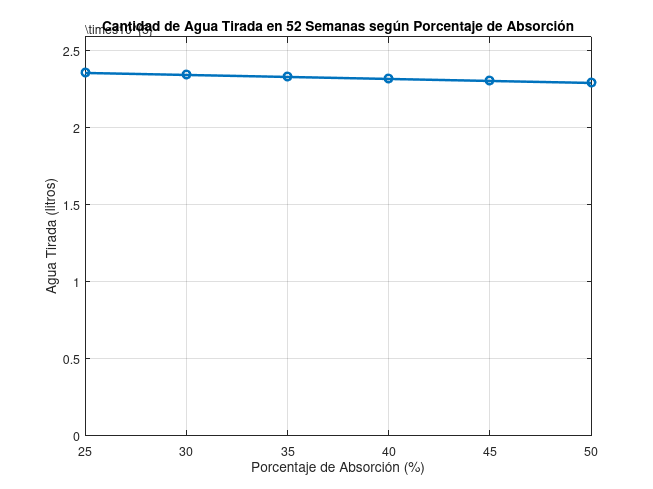


% Crear la gráfica
figure;
plot(porcentajes_absorcion * 100, agua_tirada_total_anual, '-o', 'LineWidth', 2);
xlabel('Porcentaje de Absorción (%)');
ylabel('Agua Tirada (litros)');
title('Cantidad de Agua Tirada en 52 Semanas según Porcentaje de Absorción');
grid on;
xlim([25 50]);
ylim([0 max(agua_tirada_total_anual)*1.1]);



agua_tirada_total_anual

agua_tirada_total_anual = 1.0e+05 *

    2.3521    2.3391    2.3261    2.3131    2.3001    2.2871


litros = mean(agua_tirada_total_anual)

litros = 2.3196e+05

diario = litros/365

diario = 635.4991

diario_m3=diario/1000

diario_m3 = 0.6355

m3 = litros/1000

m3 = 231.9572

ans = 8.2405e+04